clear all;
close all;
filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data1.txt';
delimiter = ',';


A = importdata(filename);
inputs= A(:,1);

outputs = A(:,2);


a) Visualize the training data set in file P1-data1.txt by plotting the output variable against the input variable. 							 

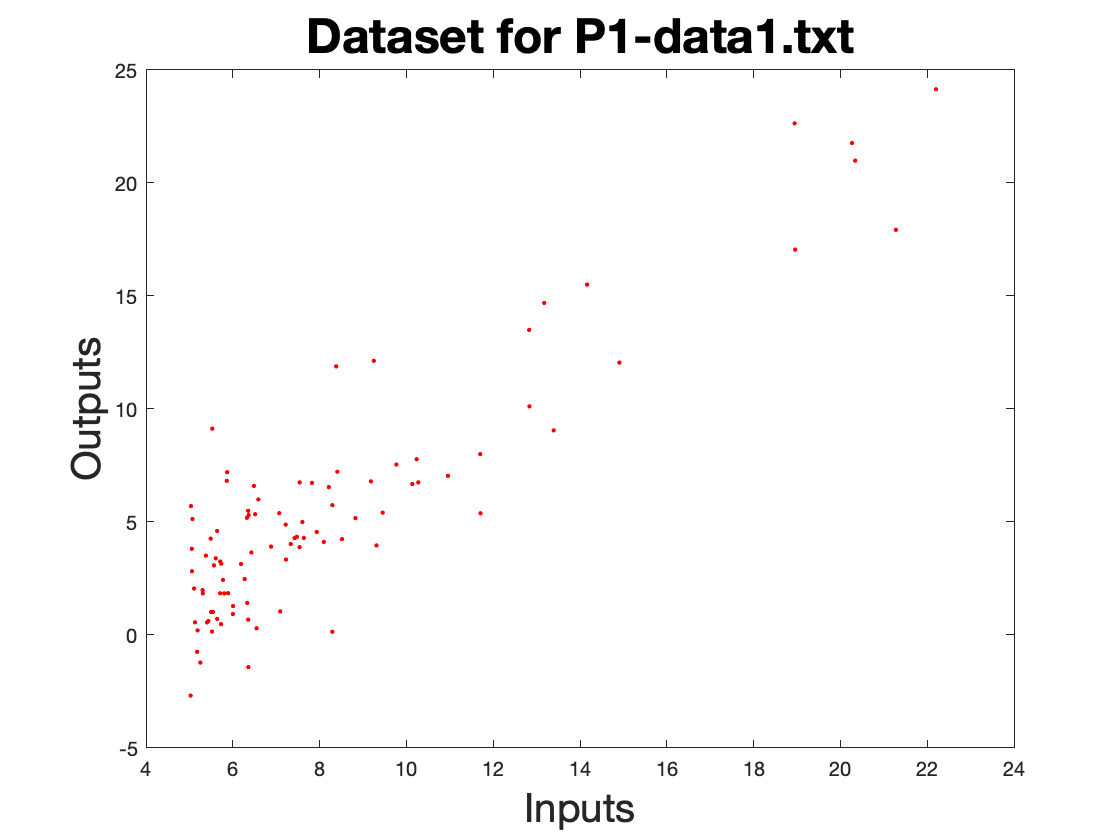

plot(inputs,outputs,'r.');
xlabel('Inputs',"FontSize",20);
ylabel('Outputs',"FontSize",20);
title('Dataset for P1-data1.txt',"FontSize",24);

b) Consider the linear regression model: f(x) = β0 +β1x, where x is the input variable. Here, f(x) is also called the hypothesis function. Assuming squared loss, plot the loss function for the following range of the learning parameters: −10 ≤ β0 ≤ 10 and −2 ≤ β1 ≤ 4. From the plot that you get, can you infer if the loss function has a global minimum? Justify your answer for full credit. 	

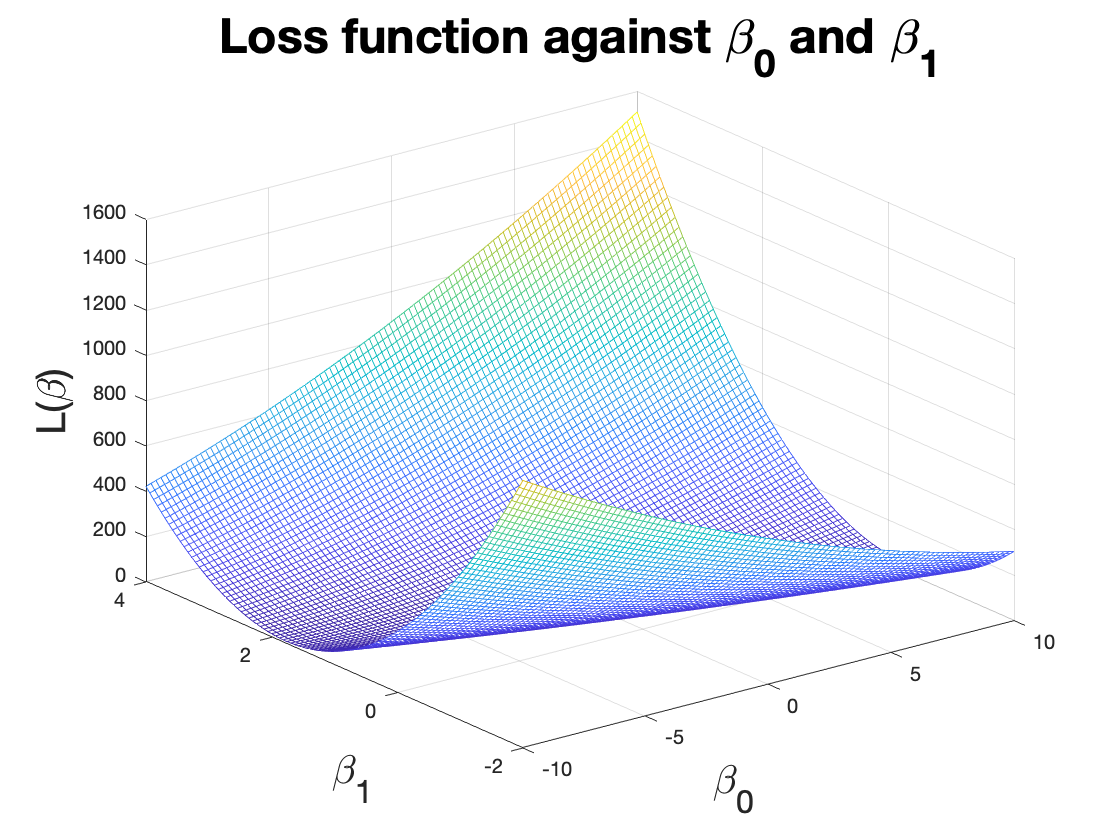

n_0 = 100;
n_1 = 100;
B_0=linspace(-10,10,n_0);
B_1=linspace(-2,4,n_1);


Beta_row_1 = repelem(B_0,length(B_1));
Beta_row_2 = repmat(B_1,1,length(B_0));
Beta_try = [Beta_row_1;Beta_row_2];
Beta=transpose(Beta_try);

%Beta_mess = [B_0; B_1];
%Beta = transpose(Beta_mess);

input_1x =[ones(1,93); transpose(inputs)];

y_caps = Beta* input_1x;

error= y_caps - transpose(outputs);

sqr_error = error.^2;
loss_func = sqr_error/length(outputs);

L_beta = sum(loss_func,2);

L_beta_mat = reshape(transpose(L_beta),[length(B_0),length(B_1)]);

mesh(B_0,B_1,L_beta_mat);
xlabel('\beta_{0}',"FontSize",20);
ylabel('\beta_{1}',"FontSize",20);
zlabel('L(\beta)',"FontSize",20);
title('Loss function against \beta_{0} and \beta_{1}',"FontSize",24);

From the plot, we cannot infer if we have reached global minimum or not. Reasons are: 

1)  The range of \beta_{0} and \beta_{1} are limited.

2) the given lowest value might be local minimum. 

c) Fit the learning parameters β0 and β1 to the training data set in P1-data1.txt using the gradient descent algorithm. For the gradient decent algorithm, consider the learning rate to be 10−2 and the number of iterations to be 1500. Initialize both β0 and β1 to 0. Using the values of β0 and β1 obtained from the above procedure, plot the hypothesis function along with the training data set. 						

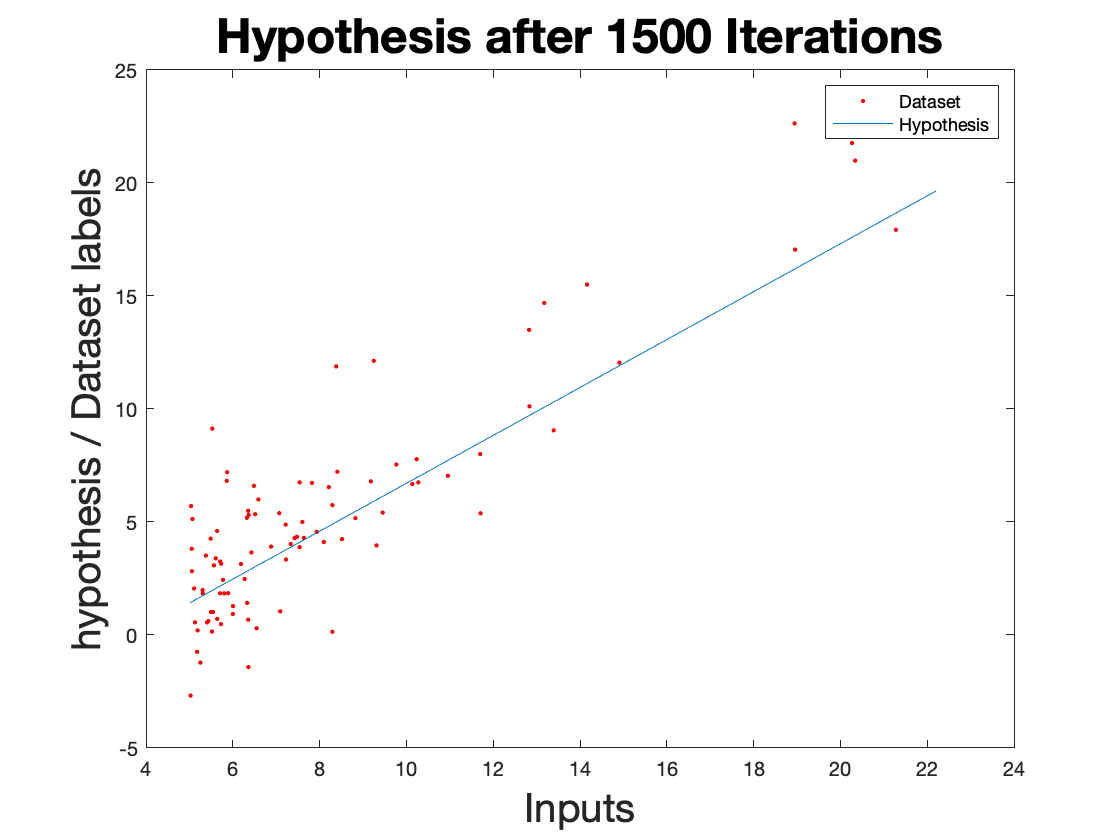

A = importdata(filename);
inputs= A(:,1);
outputs = A(:,2);
B_0=0;
B_1=0;
Beta = [B_0 B_1];
iterations = 1500;
learn_rate = 0.01; 
Beta_update = zeros(length(inputs),2);

for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs)
        
        y_caps(i) = B_0 + B_1 * inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate *error);
        B_1 = B_1 - (learn_rate *error*inputs(i));
        Beta_update(i,:) = [B_0 B_1];
        
        
    end
    

end
hyp = Beta_update(length(inputs),:) * input_1x;
plot(inputs,outputs,'r.');
hold on;
plot(inputs,hyp);
title('Hypothesis after 1500 Iterations',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
legend({'Dataset','Hypothesis'});
hold off;

d)Repeat (c) for the learning rate values of 10−6 and 3×10−2. Keep the same number of iterations. 						

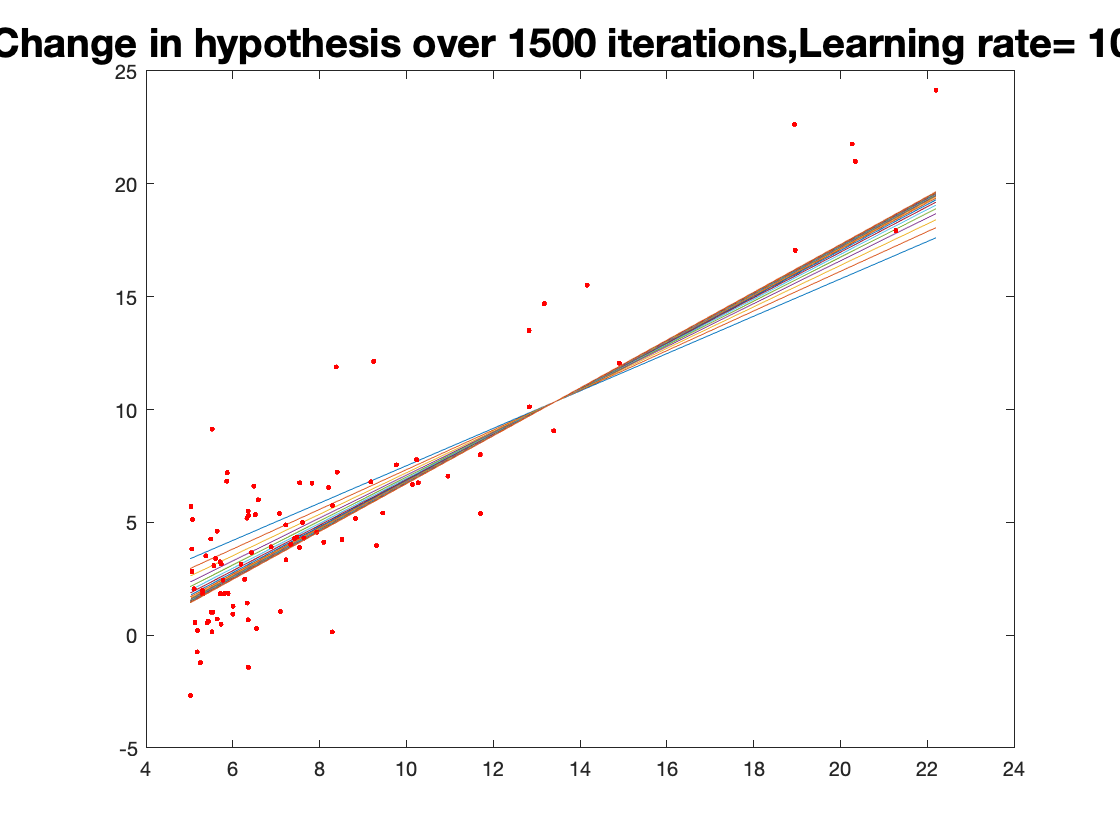

learn_rate1 = 10^-2;
B_0=0;
B_1=0;

for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs) 
        y_caps(i) = B_0 + B_1 * inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate1 *error);
        B_1 = B_1 - (learn_rate1 *error*inputs(i));
        Beta_update(i,:) = [B_0 B_1];
    end
hyp1 = Beta_update(length(inputs),:) * input_1x;
plot(inputs,outputs,'r.');
title('Change in hypothesis over 1500 iterations,Learning rate= 10^-2',"FontSize",20);
hold on;
plot(inputs,hyp1);

end

hold off;

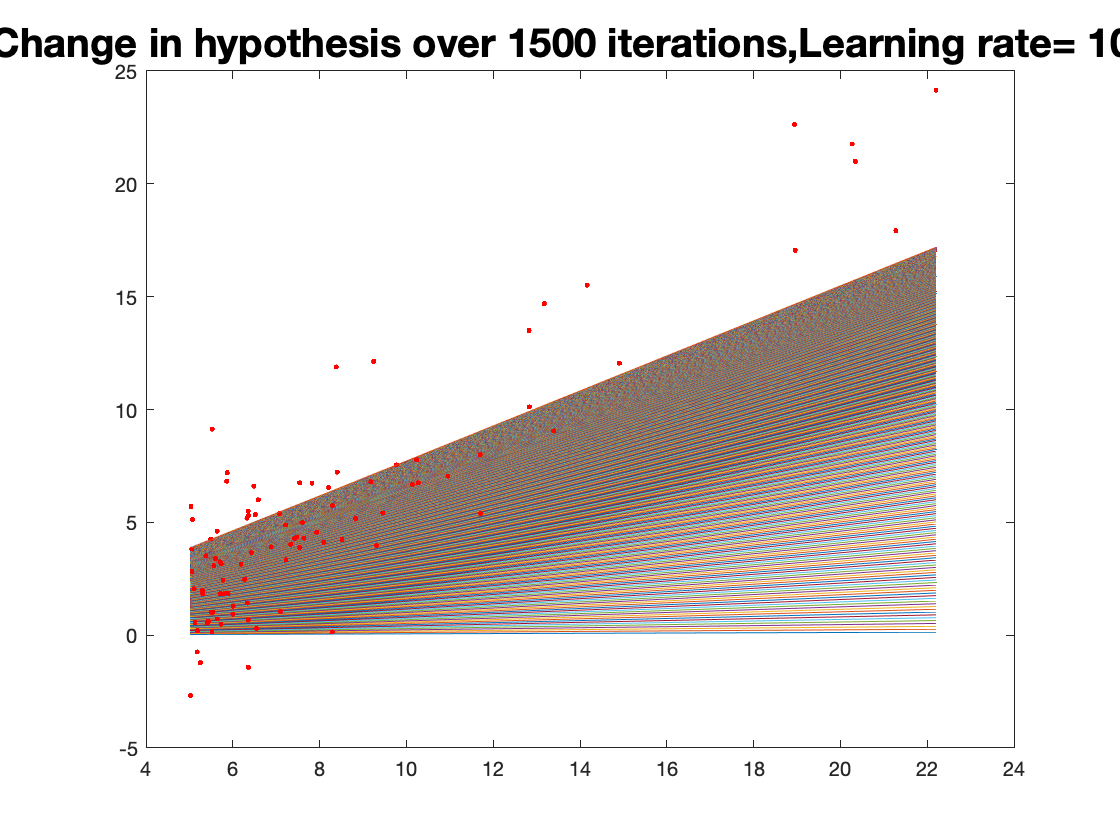


learn_rate2 = 10^-6;
B_0=0;
B_1=0;

for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs) 
        y_caps(i) = B_0 + B_1 * inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate2 *error);
        B_1 = B_1 - (learn_rate2 *error*inputs(i));
        Beta_update(i,:) = [B_0 B_1];
    end
hyp2 = Beta_update(length(inputs),:) * input_1x;
plot(inputs,outputs,'r.');
title('Change in hypothesis over 1500 iterations,Learning rate= 10^-6',"FontSize",20);
hold on;
plot(inputs,hyp2);

end

hold off;

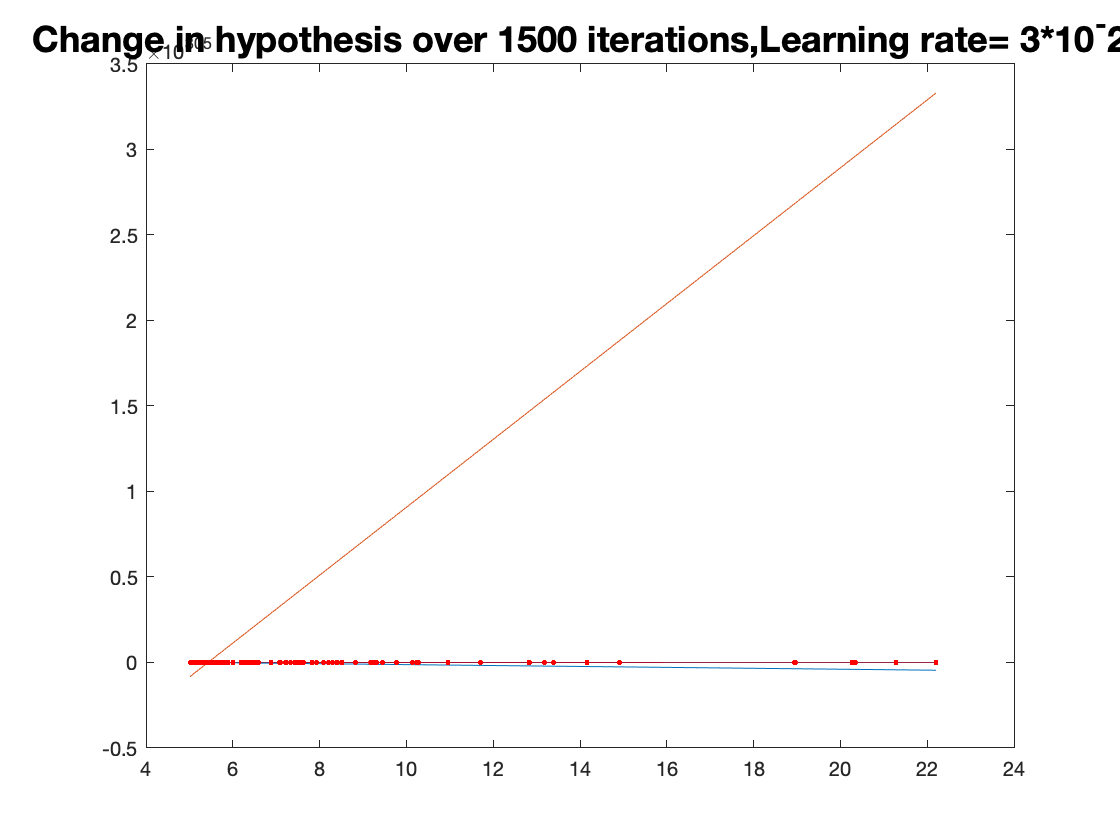


learn_rate3 = 3*(10^-2);

B_0=0;
B_1=0;
for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs)
        
        y_caps(i) = B_0 + B_1 * inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate3 *error);
        B_1 = B_1 - (learn_rate3 *error*inputs(i));
        Beta_update(i,:) = [B_0 B_1];
        
        
    end
hyp3 = Beta_update(length(inputs),:) * input_1x;
plot(inputs,outputs,'r.');
title('Change in hypothesis over 1500 iterations,Learning rate= 3*10^-2',"FontSize",18);
hold on;
plot(inputs,hyp3);


end
hold off

e) From the plots that you obtained in (c) and (d), which hypothesis function would you use to fit the training data set? State clearly why the other hypothesis functions were not chosen. 						

Answer: As shown in the last three Figures(4),(5),(6), The best learning rate would be 10^-6. From Figure 5,We can see the step size getting decreased so that there is a smooth convergence to the best hypothesis function.

1) learning rate = 10^-2  has a tendency to oscillate while converging to the local minima. The decrease in the step size is not small enough to reduce the convergence speed gently.

2) 3*10^-2 gives overshoot results. As one can see from the Figure 6, the hypothesis function is at 10^305 range on y axis.Hence, It is definetly not the best choice.

f) Compare the values of the learning parameters obtained by gradient descent algorithm in (c) with the ones obtained directly from the normal equation discussed in the class. 						

The learning parameters after c) are: 

B_0 = -3.88697930021484	and B_1 = 1.05994353580051

Below is the code for getting the Beta values from the equation discussed in class.

(Answer= B_0 = -4.4601  and B_1 = 1.2165) 	

Here B_0 achieved from equation is 0.5732 smaller than B_0 achieved from the iterative method is c. Similarly B_1 achived from the equation is 0.1566 bigger than B_1 achieved from the iterative method.

clear all;
close all;
filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data1.txt';
delimiter = ',';

A = importdata(filename);
inputs= A(:,1);
outputs = A(:,2);
input_1x =[ones(1,93); transpose(inputs)];

Beta =  inv(input_1x*transpose(input_1x))*input_1x *outputs;
Beta

Beta =    -4.4601
    1.2165
